# Fines migration, hydrodynamic release, and deposition (formation damage) in a five-spot well pattern - case 1

In this demonstration example we will reproduce the two-dimensional problem for formation damage caused by massive injection of a CO2-particle mixture as discussed by **Sbai and Azaroual (2011) **in their example described in section 5.1. This involves pumpage of a salt aqueous brine from a 3000m deep reservoir through four square corner's wells with an equal injection rate. CO2 phase is injected from a well at the center of the domain with a total injection flow rate of 1.15 x 10^6 tons/year. 

## Reservoir, fluids,and particulate suspensions properties setup 

Let's first specify the simple reservoir geometry which is a one layer of 500m x 500m x 5m along each space dimension. Additionally, we will explicitly store some required variables in the '`Grid`' structure as reequired for next computational tasks. These are: `Nx`, `Ny`, `Nz` which corresponds to the number of cells along each space dismension, respectively. N: the total number of grid cells, `hx`, `hy`, `hz`, which are the uniform spacing along each space dimension, `V`: the volume of grid cells, `K`: the initial distribution of the permeability, `compr` the total compressibility factor, `por`: the initial distribution of the porosity. 

% Domain size along X, Y & Z directions
dom = RecDomain([500,500,5]);
Dx = dom.Lx; Dy = dom.Ly; Dz = dom.Lz;
Grid.Nx = 101;  Grid.Ny = 101;   Grid.Nz = 1; 
Nx = Grid.Nx;   Ny = Grid.Ny;    Nz = Grid.Nz; 
Grid.hx = (Dx/Nx);
Grid.hy = (Dy/Ny);
Grid.hz = (Dz/Nz);
Grid.N = Grid.Nx*Grid.Ny*Grid.Nz;
N = Grid.N;
Grid.V = (Dx/Nx)*(Dy/Ny)*(Dz/Nz);                        % grid cells volumes
Grid.K = 0.85e-12.*ones(3,Nx,Ny,Nz);                      
Grid.compr = 4.4e-10.*ones(Grid.Nx,Grid.Ny,Grid.Nz);     % compressibility
Grid.por   = 0.3.*ones(Grid.Nx,Grid.Ny,Grid.Nz);         % porosity


Set the injection and production flow rates at the target cells:

% Cell-centered injection/production flow rates
Total      = 150/3600;                                   % /h >> /s
Qw         = zeros(N,1);
Qw([1 N])  = [-Total/4 -Total/4];
Qw(Nx)     = -Total/4;
Qw(N-Nx+1) = -Total/4;
index      = 5101;                                       % index of center well cell
Qw(index)  = Total;

Next, initialize the fluids properties for the saline water and carbon dioxide phases: 

% fluid properties units: density (Kg/m^3), viscosity (Pa.s), residual saturation (-)
water = Fluid('saltwater',      [1030, 5e-4,   0.3]);   % resident fluid
co2   = Fluid('carbon dioxide', [950,  7.7e-5, 0.3]);   % injected fluid

We set the initial pressure to 300 bars everywhere in the reservoir and the initial non-wetting phase (CO2) saturation to its residual value:

P = 300e5.*ones(Nx,Ny,Nz);
S = co2.Sr.*ones(N,1);

Let's add a group of endogeneous (i.e. external) non-wetting CO2 particles which will be injected with the CO2 phase meaning that the injected phase is composed from a mixture of CO2 fluid and particulate suspensions present in the gas stream as a result of the CO2 capture process which cannot be filtered for economic reasons.

Herein, we assue that salinity induced modibilization of fines is negligeable, hence by leting the colloidal mobilization rate equal to zero the process is effectively excluded as desired. So the processes which are effectively take into account during this simulation are:

- Hydrodynamic mobilization of fine particles for which kinetic rate equals 3.8e-4 m^-1 and the critical fluid velocity amounts to 0.2e-4 m/s

- Deposition into pore bodies with a kinetic rate constant equal to 1.2e-4 m^-1 

- Deposition into pore throats with a kinetic rate constant equal to 6.2e-6 m^-1 

pt1 = Particle(co2, ...             % fluid phase in which particles flow
               [2e-6, ...           % Mean-size diameter => for particle population
                2500, ...           % Particles density
                1e-9, ...           % Diffusion coeff => important for small size particles
                0.2e-4, ...         % Critical fluid velocity
                0.1, ...            % Critical fluid salinity
                3.8e-4, ...         % Hydrodynamic release rate
                0, ...              % Colloidal mobilisation rate
                1.2e-4, ...         % Deposition rate in pore surfaces
                6.2e-6, ...         % Deposition rate in pore throats
                0.6] ...            % For civan k_phi model
                );


Initialize different concentrations arrays for the particulate suspensions including the mobile concentration, pore surface deposited concentration, pore throats deposited concentration.

% Initialisation of concentration arrays => particle 1
pt1.C     = zeros(N,1);            % Initial mobile concentration
pt1.C_dep = zeros(N,1);            % Initial surf. deposited conc
pt1.C_pt  = zeros(N,1);            % Initial throats deposited conc
pt1.C_tsf = zeros(N,1);            % Initial mass tranfer <=> phases
Cs = zeros(N,1);                   % Initial salt concentration

Make a copy of the initial permeability and porosity fields as they will be updated by the simulator:

% Copy of initial porosity & permeability
Grid.por0 = Grid.por;
Grid.K0   = Grid.K;

Reset default options of the Newton-Raphson solver to solve the two-phase flow sub-problem. tol is the absolute tolerance for NR convergence, and maxiter is the maximum number of allowed NR iterations befor decision on divergence and local time step subdivision. 

opt.tol     = 1e-6;
opt.maxiter = 50;

Finally, set the total period of simulation, the number of time steps and the time step used for the sequential simulation algorithm between the two-phase flow sub-system and the particulate transport-kinetics sub-system:

day = 3600*24;                     % seconds/day
T   = 30*day;                      % 30 days
nt  = 30;                          % number of time steps
dt  = T/nt;                        % time step

## Sequential simulation loop 

Now that all the required data and simulation options are set, we're ready to start the simulation of two-phase flow coupled to particle transport. The main simulation loop involved mainly four steps for each global time step: 

- First, the two-phase flow (of injected CO2 and resident water) pressure solver is called.The cell-centered pressure is updated after evaluation of each fluid mobility using the non-wetting phase saturation from the previous time step 

- Second, the two-phase flow saturation solver is called to update the distribution of the non-wetting phase saturation during this time step. Unlike the pressure solver which is linear the saturation equation is nonlinear. The numerical solution uses an algorithm which repeatedely subdivise the initial time step into internal sub-steps if the most inner Newton-Raphson (NR) iteration loop does not converge during the prescribed number of iterations. This adaptive algorithm is robust and efficient since the Jacobian of the minimized  residuals during the NR iteration is evaluated analytically. 

- Once one pressure-saturation are solved, we transport the particles which involves splitting of their convective, kinetic, and diffusive solves.

- Finally, porosity and subsequent permeability change in each grid cell are evaluated and are both updated for the next time step. 

tic;              % start timing the time marching loop
for t=1:nt
   fprintf('\n'); 
   fprintf('Solving two-phase flow problem. Time = %f days\n', t*dt/day);
   
   % call TPFA flow solver adapted to two-phase flow 
   [P,V] = TwoPhasePressure(Grid,S,co2,water,Qw,P,dt); 
   
   % solve for brine saturation 
   S = ImplicitSaturation(Grid,S,co2,water,V,Qw,dt,opt);
   Grid.sat = reshape(S,Grid.Nx,Grid.Ny,Grid.Nz);
   
   % particles transport solve 
   [m1,~] = RelativePerm(S,co2,water);
   [~,V1] = TwoPhasePressure(Grid,m1.*S,co2,water,Qw);
   pt1 = pt1.transport(Grid,V1,Qw,Cs,dt);
   
   % evaluate porosity and permeability change 
   Grid.por0 = reshape(Grid.por0,N,1);
   Grid.por  = reshape(Grid.por,N,1);
   Grid.por  = Grid.por0 - ( (pt1.C_dep + pt1.C_pt) / pt1.density);
   f = abs(ones(N,1) - pt1.alpha_fe.*pt1.C_pt); % distributed flow efficiency factor
   k_ratio = EvalPermeabilityCivan(Grid.por0,Grid.por,0,f,3);
   Grid.por0 = reshape(Grid.por0,Grid.Nx,Grid.Ny,Grid.Nz);
   Grid.por  = reshape(Grid.por,Grid.Nx,Grid.Ny,Grid.Nz);
   
   k_ratio = reshape(k_ratio,1,Grid.Nx,Grid.Ny,Grid.Nz);
   for l=1:3
       Grid.K(l,:,:,:) = Grid.K0(l,:,:,:) .* k_ratio(1,:,:,:);
   end
   k_ratio = reshape(k_ratio,N,1);

end

Solving two-phase flow problem. Time = 1.000000 days


......
Converged in 7 time sub-steps and 221 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 2.000000 days


..
Converged in 3 time sub-steps and 21 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 3.000000 days


.
Converged in 2 time sub-steps and 13 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 4.000000 days


Converged in 1 time sub-steps and 16 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 5.000000 days


Converged in 1 time sub-steps and 7 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 6.000000 days


..
Converged in 3 time sub-steps and 19 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 7.000000 days


Converged in 1 time sub-steps and 8 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 8.000000 days


.
Converged in 2 time sub-steps and 10 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 9.000000 days


Converged in 1 time sub-steps and 8 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 10.000000 days


Converged in 1 time sub-steps and 8 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 11.000000 days


Converged in 1 time sub-steps and 8 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 12.000000 days


Converged in 1 time sub-steps and 8 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 13.000000 days


Converged in 1 time sub-steps and 9 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 14.000000 days


Converged in 1 time sub-steps and 15 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 15.000000 days


Converged in 1 time sub-steps and 5 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 16.000000 days


Converged in 1 time sub-steps and 5 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 17.000000 days


Converged in 1 time sub-steps and 4 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 18.000000 days


Converged in 1 time sub-steps and 4 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 19.000000 days


Converged in 1 time sub-steps and 4 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 20.000000 days


Converged in 1 time sub-steps and 4 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 21.000000 days


Converged in 1 time sub-steps and 4 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 22.000000 days


Converged in 1 time sub-steps and 4 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 23.000000 days


Converged in 1 time sub-steps and 4 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 24.000000 days


Converged in 1 time sub-steps and 4 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 25.000000 days


Converged in 1 time sub-steps and 3 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 26.000000 days


Converged in 1 time sub-steps and 3 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 27.000000 days


Converged in 1 time sub-steps and 3 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 28.000000 days


Converged in 1 time sub-steps and 3 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 29.000000 days


Converged in 1 time sub-steps and 3 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


Solving two-phase flow problem. Time = 30.000000 days


Converged in 1 time sub-steps and 3 Newton-Raphson iterations


Newton-Raphson iteration converged in 1 steps


toc;

Elapsed time is 1459.335985 seconds.


During each time step the output log reports the number of sub-steps and total NR iterations spent to solve the nonlinear saturation equation. Note that each NR iteration corresponds to one call to the inner sparse linear solver whose size equals the number of gid cells. For instance we use the MATLAB backslash `\` operator (i.e. `mldivide` direct solver) which is based on [UMFPACK](http://faculty.cse.tamu.edu/davis/suitesparse.html) to solve the inner linear systems. In later versions of this toolkit we plan to introduce iterative Krylov linear solvers with preconditioning which are more efficient for large scale problems. 

## Results visualization and analysis 

 One important benefit to use a scripting language for numerical simulation tasks is to break the boundaries between model pre-processing, processing, and post-processing. 

In the first stage of this tutorial all needed data was prepared in the same script before going into model execution. This task could be achieved with more efficiency even for reservoirs with much complex geometry and distributed materials and fluids properties. 

Now, we will show how to immediately plot the obtained results at the simulation end without going into storing all computational results into files in open or proprietary formats for post-processing by a third party visualization package. We will plot spatial distributions of the reservoir presuure, P, the carbon dioxide saturation, S, the concentrations of mobile, and pore bodies/throats deposits, and the permeability reduction factor K/K0 (where K0 is the initial reservoir permeability). Herein, we simply use the `contourf` command to plot filled contour lines of each variable. All subplots are arranged in a 3 x 2 matrix using the `subplot` command for reporting compactness and each sub-figure has its own title. 

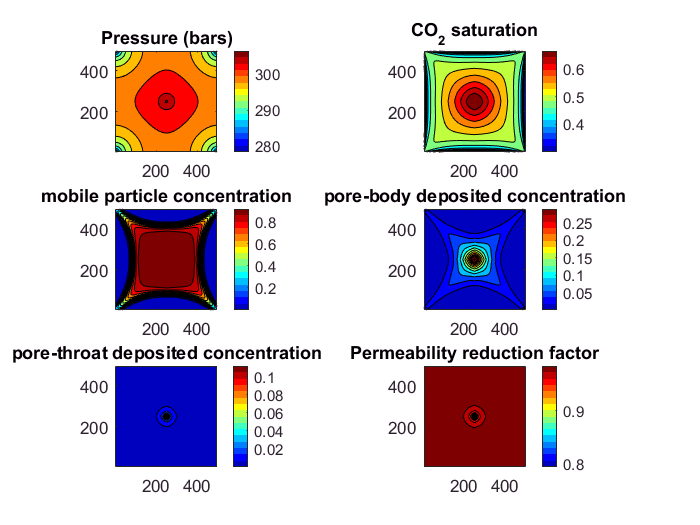

figure; 

% plot fluid pressure 
subplot(3,2,1);
contourf(linspace((Dx/Nx)/2,Dx-(Dx/Nx)/2,Nx),...
         linspace((Dy/Ny)/2,Dy-(Dy/Ny)/2,Ny),...
         reshape(P,Nx,Ny)'*1e-5,11);
colormap(jet(16));
axis tight equal; colorbar, title('Pressure (bars)');

% plot CO2 saturation 
subplot(3,2,2);
contourf(linspace((Dx/Nx)/2,Dx-(Dx/Nx)/2,Nx),...
         linspace((Dy/Ny)/2,Dy-(Dy/Ny)/2,Ny),...
         reshape(S,Nx,Ny)',11);
colormap(jet(16));
axis tight equal; colorbar, title('CO_2 saturation');

% mobile co2 particles 
subplot(3,2,3);
contourf(linspace((Dx/Nx)/2,Dx-(Dx/Nx)/2,Nx),...
         linspace((Dy/Ny)/2,Dy-(Dy/Ny)/2,Ny),...
         reshape(pt1.C,Nx,Ny)',11);
colormap(jet(16));
axis tight equal; colorbar, title('mobile particle concentration');

% deposited co2 particles on pore bodies
subplot(3,2,4);
contourf(linspace((Dx/Nx)/2,Dx-(Dx/Nx)/2,Nx),...
         linspace((Dy/Ny)/2,Dy-(Dy/Ny)/2,Ny),...
         reshape(pt1.C_dep,Nx,Ny)',11);
colormap(jet(16));
axis tight equal; colorbar, title('pore-body deposited concentration');

% deposited co2 particles on pore throats
subplot(3,2,5);
contourf(linspace((Dx/Nx)/2,Dx-(Dx/Nx)/2,Nx),...
         linspace((Dy/Ny)/2,Dy-(Dy/Ny)/2,Ny),...
         reshape(pt1.C_pt,Nx,Ny)',11);
colormap(jet(16));
axis tight equal; colorbar, title('pore-throat deposited concentration');

% plot permeability reduction factor
subplot(3,2,6);
contourf(linspace((Dx/Nx)/2,Dx-(Dx/Nx)/2,Nx),...
         linspace((Dy/Ny)/2,Dy-(Dy/Ny)/2,Ny),...
         reshape(k_ratio,Nx,Ny)',11);
colormap(jet(16));
axis tight equal; colorbar, title('Permeability reduction factor');

The obtained results reproduce exactly those presented in Figure 6 of Sbai and Azaroual (2011) paper. Mobile particles concentration is most important in a circular zone arround the injection well where CO2 velocity fraction exceeds the prescribed critical velocity leading to hydrodynamic release of particles already deposited in this area. Pore body deposited concentration distribution shape closely follows that of the mobile concentration but with a reversed gardient which is much higher arround the injector. Pore throat deposits and the permeability reduction factor are more restricted to a small radial zone arround the injection well.   